% Solicitar el punto inicial y el error permitido
x0 = input('Ingrese el valor del punto inicial: ');
e = input('Ingrese el valor del error permitido: ');

% Verificar que el error sea positivo
while e <= 0
    disp('Error: El error no puede ser negativo o cero.');
    e = input('Ingrese un valor positivo para el error: ');
end

% Definir la función f(x)
f = @(x) 1 - x^2 - atan(x);

% Definir la derivada de la función f'(x)
df = @(x) -2*x - (1 / (1 + x^2));

% Inicializar variables para la iteración
x_actual = x0;
error_actual = abs(f(x0)) + 1;
iteracion = 0;

% Ciclo de Newton-Raphson
while error_actual > e
    iteracion = iteracion + 1;
    
    % Calcular el nuevo valor de x utilizando Newton-Raphson
    x_nuevo = x_actual - f(x_actual) / df(x_actual);
    
    % Calcular el error relativo
    error_actual = abs((x_nuevo - x_actual) / x_nuevo) * 100;
    
    % Actualizar el valor de x para la siguiente iteración
    x_actual = x_nuevo;
end

% Mostrar el resultado
fprintf('La raíz más aproximada es: %.6f\n', x_actual);

La raíz más aproximada es: 0.650561


fprintf('Con un error de: %.6f Porciento\n', error_actual);

Con un error de: 0.003764 Porciento


fprintf('La raíz se encontró en la iteración número: %d\n', iteracion);

La raíz se encontró en la iteración número: 3


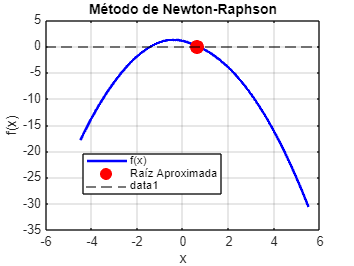

% ---------- GRAFICAR LA FUNCIÓN ----------

% Crear un vector de valores para graficar la función
x_vals = linspace(x0 - 5, x0 + 5, 1000);  % Intervalo de la gráfica centrado alrededor de x0
y_vals = arrayfun(f, x_vals);   % Evaluar la función en esos puntos

% Graficar la función
figure;
plot(x_vals, y_vals, 'b-', 'LineWidth', 2);  % Graficar la función
hold on;
grid on;

% Marcar la raíz encontrada en la gráfica
plot(x_actual, f(x_actual), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

% Añadir etiquetas y título
xlabel('x');
ylabel('f(x)');
title('Método de Newton-Raphson');
legend('f(x)', 'Raíz Aproximada');

% Marcar el eje x
yline(0, 'k--');